# Inverse problems

## Calculated A

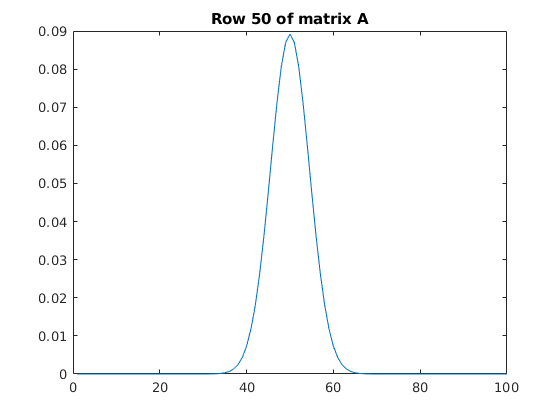

clearvars
clc
close all
ImportData

t = 0.001; % s
y = OppgA;
N = 100;
A = zeros(N,N);
for i = 1:N
    xi = (i-1)*(1/N);
    for j = 1:N
        xj = (j-1)*(1/N);
        dist = min(mod(xi-xj,1),mod(xj-xi,1)); % Modular distance
        A(i,j) = (1/(N*sqrt(4*pi*t)))*exp(-(dist^2)/(4*t));
    end
end
figure
plot(A(50,:));
title("Row 50 of matrix A")

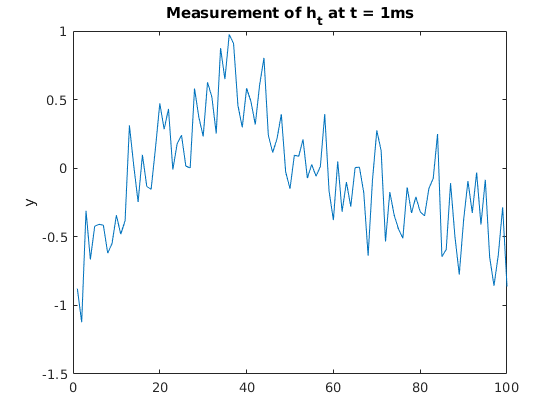


figure
plot(y)
ylabel("y")
title("Measurement of h_t at t = 1ms")

## Naive solution

h0 = A^(-1)*y;

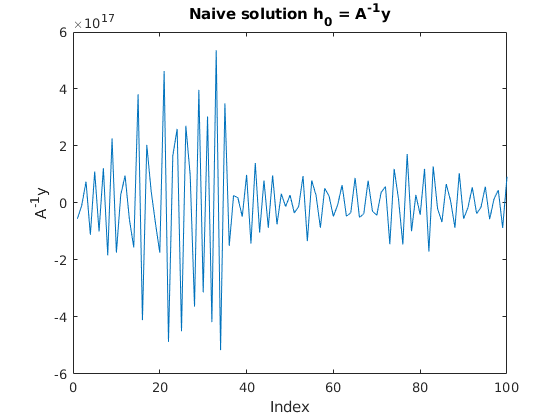

figure
plot(h0)
xlabel("Index")
ylabel("A^{-1}y")
title("Naive solution h_0 = A^{-1}y")

## Eigenvalues

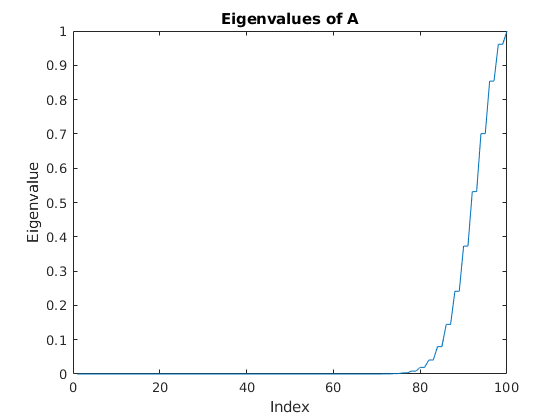

lambda = eig(A); % Reveresed order compared to svd()
figure
plot(lambda);
xlabel("Index");
ylabel("Eigenvalue");
title("Eigenvalues of A")

## Singular value decompesition

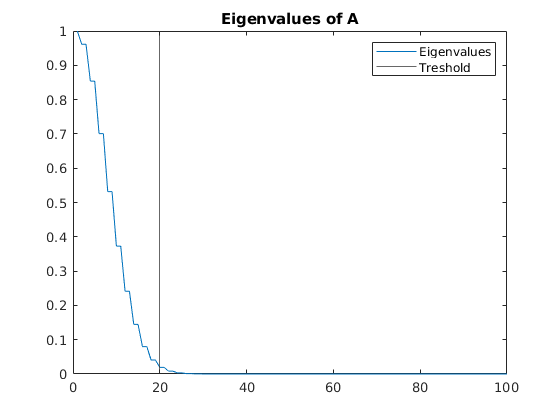

[U,S,V] = svd(A); % A == U*S*V'
% Should maybe calculated these manually from eigenvalues?
k = 20; % Trunkation treshold
figure
plot(diag(S))
hold on
xline(k);
hold off
title("Eigenvalues of A")
legend("Eigenvalues","Treshold")

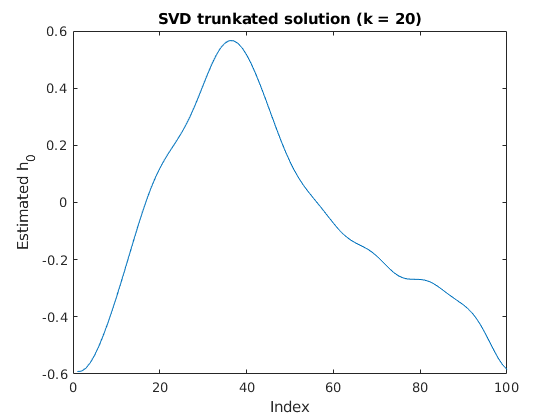


S(k:end,k:end) = 0;
S_inv = S'; % Square and diagonal matrix: inverse equals transport


h0 = V*S_inv*U'*y;
figure
plot(h0);
xlabel("Index")
ylabel("Estimated h_0")
title(['SVD trunkated solution (k = ',num2str(k),')']);

## Gausian Prior

priorMean = 0;
priorCov = eye(100);
% From page 24, line 4 on the lecture notes, we see the distrobution of h_0 | y,  
% assumeing gausion measurment noise is given as f(x|y) = const* exp(-1/2[y-Ax)^T ...)
% Assuming this should also be a gauusian distrobution we can calculate E
% and var:
